# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 박명근**

**학번**** : 201716008**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

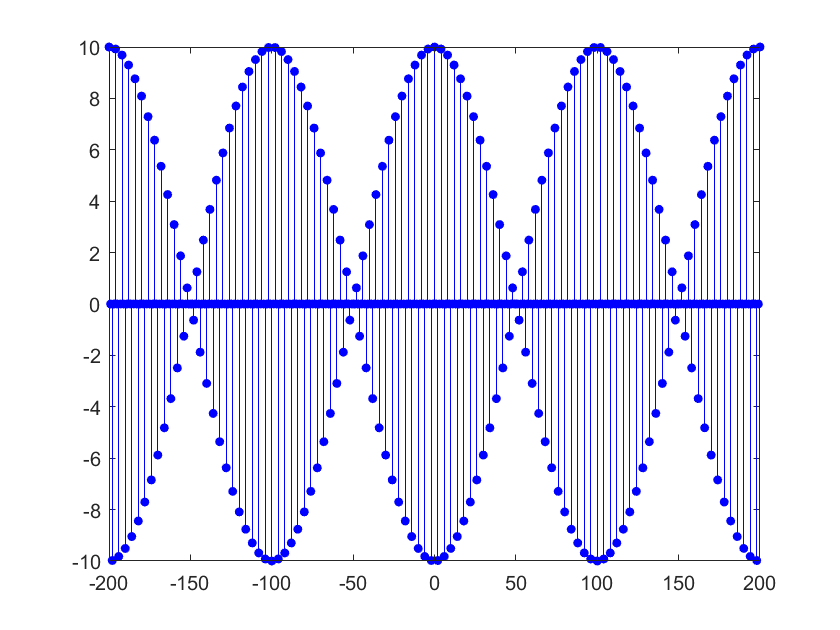

figure()
n1 = -200:200;
x5_n = 5*(cos(0.49*pi*n1) + cos(0.51*pi*n1));

Hs = stem(n1, x5_n, 'b', 'filled');
set(Hs, 'markersize', 4);

2) 

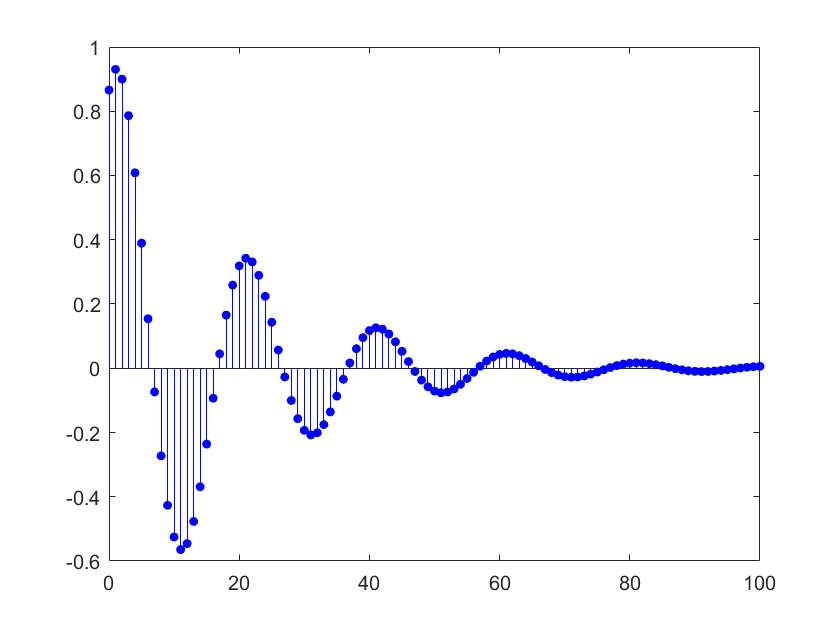

figure()
n2 = 0:100;
x7_n = exp(-0.05.*n2).*sin(0.1.*pi.*n2 + pi ./ 3);

Hs = stem(n2, x7_n, 'b', 'filled');
set(Hs, 'markersize', 4);

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

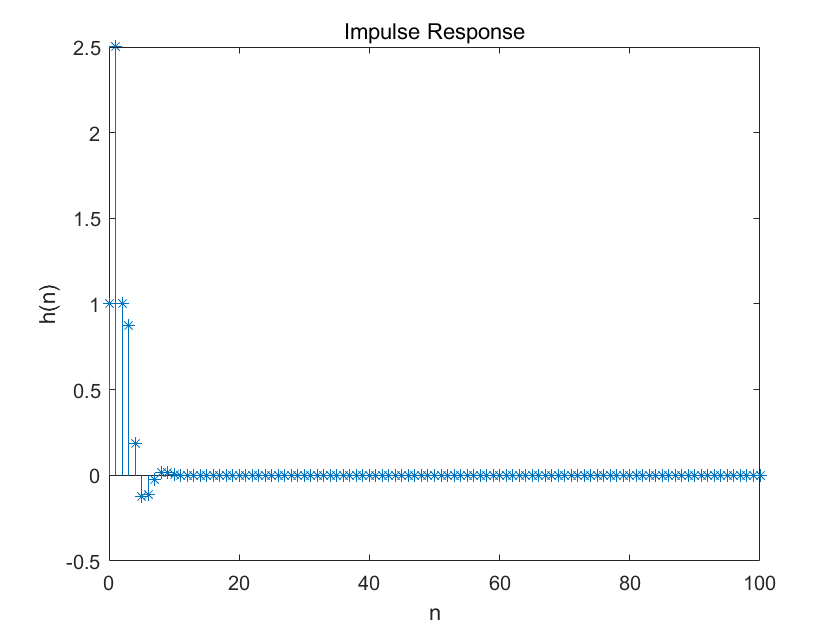

figure()
b = [1, 2, 0, 1]; 
a = [1, -0.5, 0.25];
n = 0:100;
h = impz(b, a, n);
stem(n, h, '*');
title('Impulse Response'); xlabel('n'); ylabel('h(n)'); 

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h)) % 출력한 결과가 무한대보다 작으므로 stable 이다.

ans = 5.8571

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

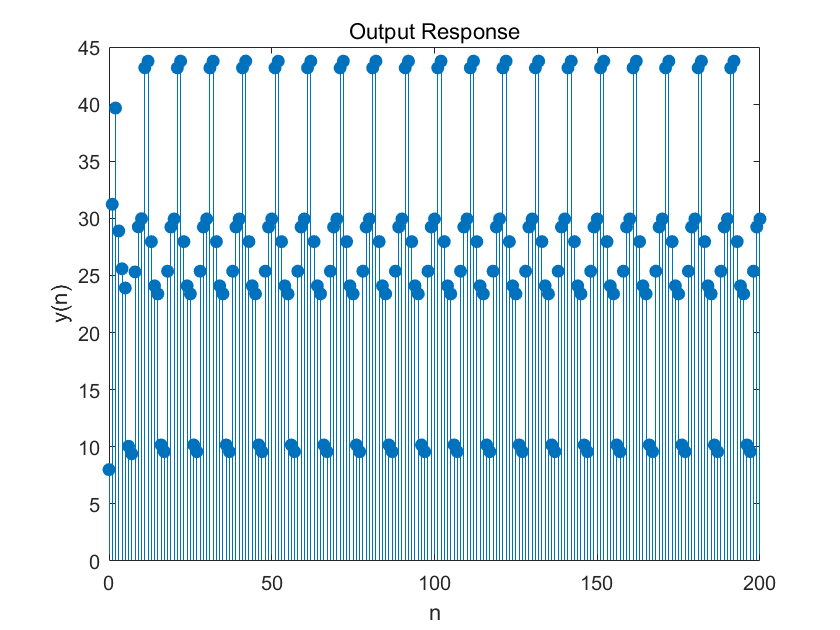

figure()
b = [1, 2, 0, 1]; 
a = [1, -0.5, 0.25];
n = 0:200;
x = 5 + 3 * cos(0.2 * pi * n) + 4 * sin(0.6 * pi * n);
y = filter(b, a, x);

Hs = stem(n, y, "filled");
xlabel('n'); ylabel('y(n)');
title('Output Response');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

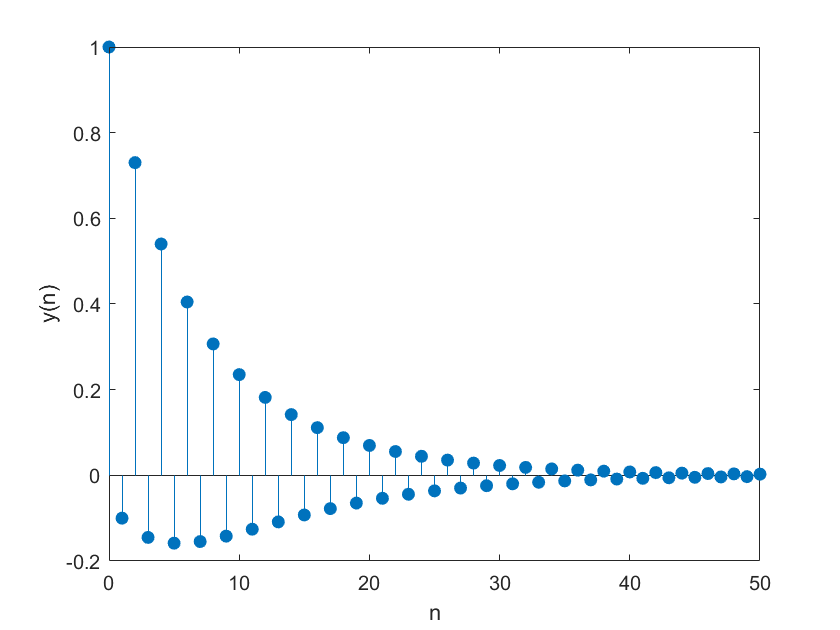

figure()
n = [0:50];
x = 0.8.^n;
h = (-0.9).^n;

y = ((0.8) .^ (n + 1) - (-0.9) .^ (n + 1)) / (0.8 + 0.9);
Hs1 = stem(n, y, 'filled');
xlabel('n'); ylabel('y(n)');

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

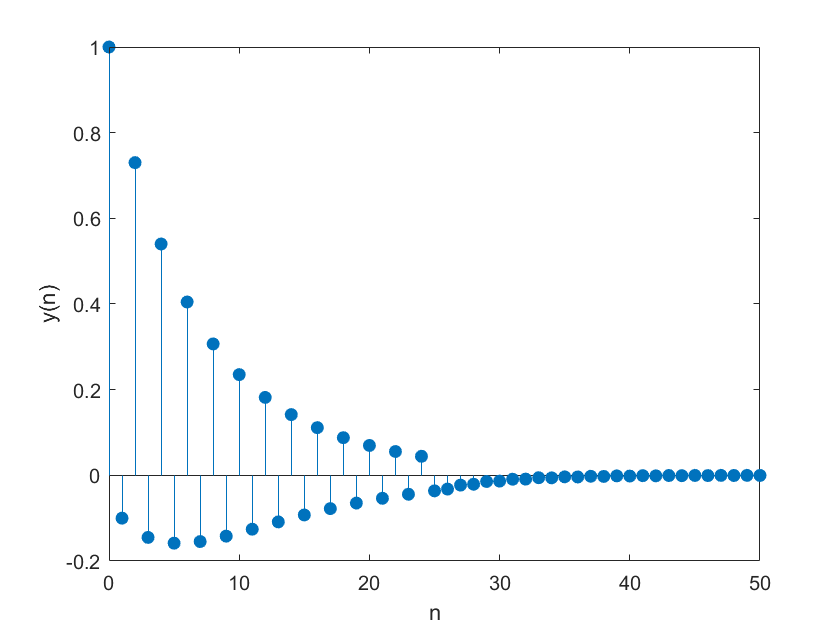

n = [0:50];
x = 0.8.^n;
h = (-0.9).^n;

x = x(1:26);
h = h(1:26);
y = conv(h, x);

Hs = stem(n, y, 'filled');
xlabel('n'); ylabel('y(n)');

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

figure()
n = [0:50];
x = 0.8.^n;

y = filter([1], [1, 0.9], x);
Hs = stem(n, y, 'filled');
xlabel('n'); ylabel('y(n)');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

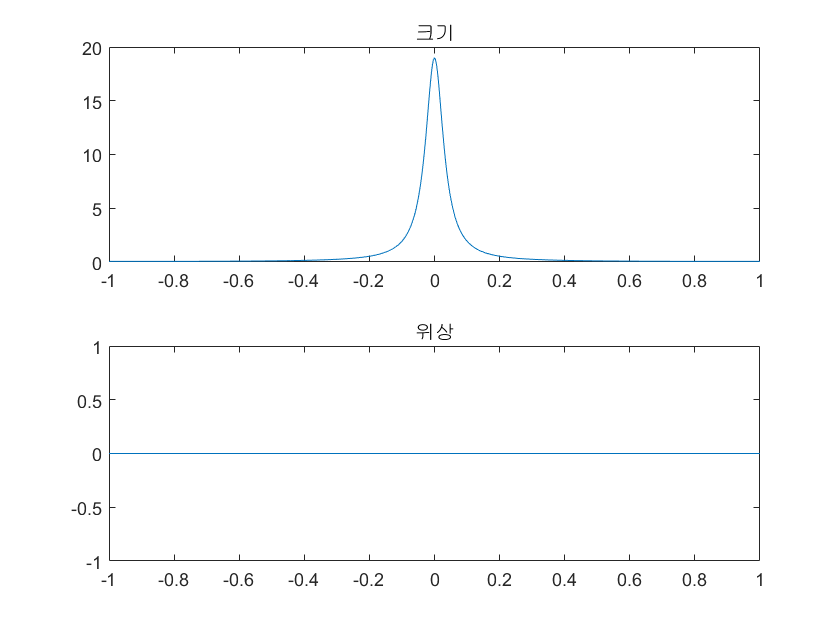

W = [-300:300] * pi / 300; 
H = 0.19 ./ (1.81 - 1.8 * cos(w));
magnitude = abs(H); 
phase = angle(H) * 180 / pi;

figure()
subplot(2, 1, 1);
plot(w / pi, magnitude);
title('크기');

subplot(2,1,2);
plot(w / pi, phase);
title('위상');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

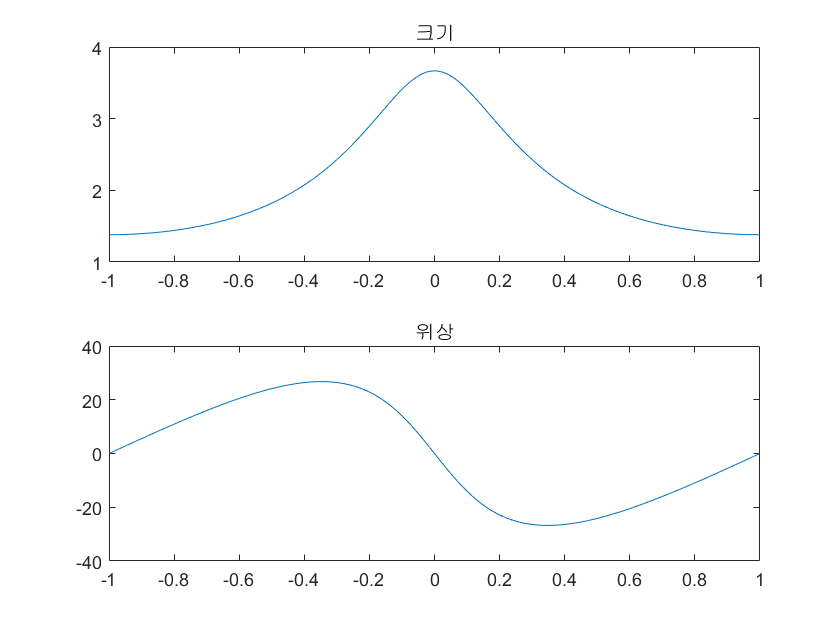

w = [-300:300] * pi / 300; 
H = (2 - 0.9 * exp(-j * w)) ./ (1 - 0.9 * exp(-j * w) + 0.2 * exp(-j * 2 * w));
magnitude = abs(H);
phase = angle(H) * 180 / pi;

figure()
subplot(2, 1, 1);
plot(w / pi, magnitude);
title('크기');

subplot(2, 1, 2);
plot(w / pi, phase);
title('위상');

5. (P3.17) 

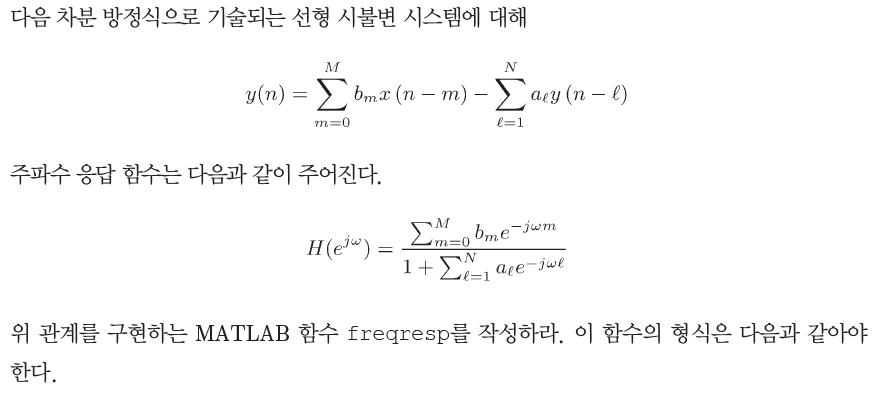

% function [H] = freqresp(b,a,w)
%    %H = frequency response array evaluated at w frequencies
%    %b = numerator coefficient array
%    %a = denominator coefficient array (a(1) = 1)
%    %w = frequency location array

% b = reshape(b, 1, length(b));
% a = reshape(a, 1, length(a));
% w = reshape(w, 1, length(w));
% m = 0 : length(b) - 1;
% num = b * exp(-j * m' * w);
% l = 0 : length(a) - 1;
% denom = a * exp(-j * l' * w);
% H = num ./ denom;
% end

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

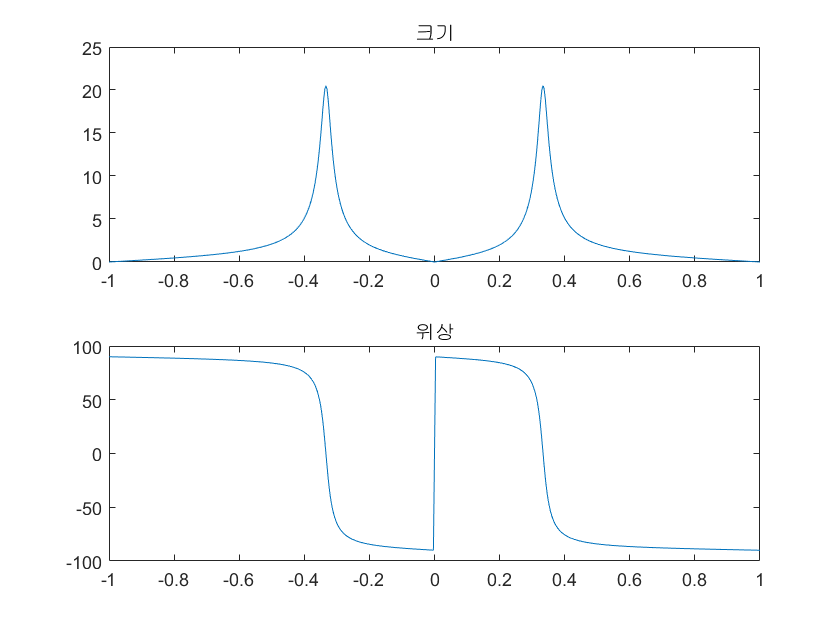

w = [-300:300] * pi / 300; 
a = [1, -0.95, 0.9025]; 
b = [1, 0, -1];

[H] = freqresp(b, a, w); 
magnitude = abs(H);
phase = angle(H) * 180 / pi;

figure(1)
subplot(2, 1, 1);
plot(w / pi, magnitude);
title('크기');

subplot(2,1,2);
plot(w / pi, phase);
title('위상');

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

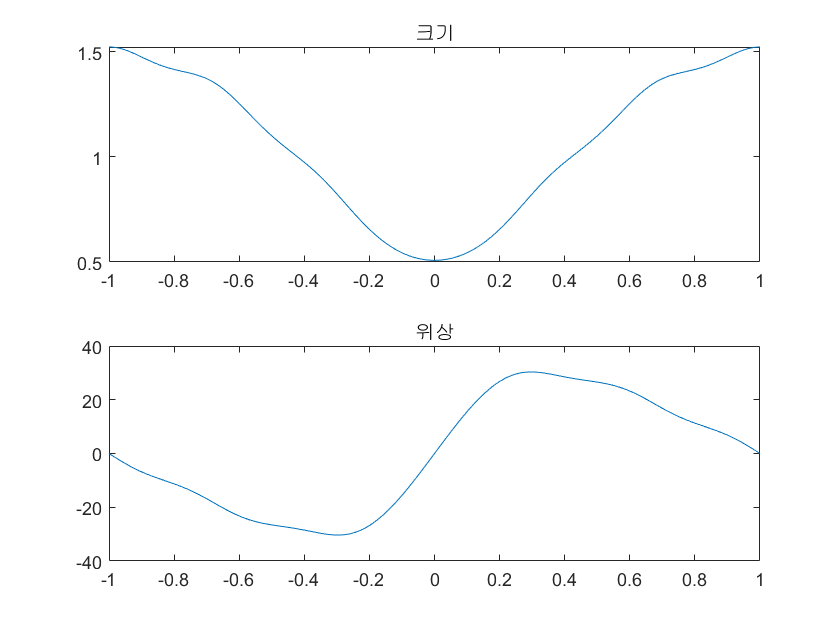

W = [-300:300] * pi / 300; 
l = [0:5]; 
a = 0.5 .^ l;
b =[1];

[H] = freqresp(b, a, w);
magnitude = abs(H);
phase = angle(H) * 180 / pi;

figure(2)
subplot(2, 1, 1);
plot(w / pi, magnitude);
title('크기');

subplot(2, 1, 2);
plot(w / pi, phase);
title('위상');

function [H] = freqresp(b,a,w)
   %H = frequency response array evaluated at w frequencies
   %b = numerator coefficient array
   %a = denominator coefficient array (a(1) = 1)
   %w = frequency location array

b = reshape(b, 1, length(b));
a = reshape(a, 1, length(a));
w = reshape(w, 1, length(w));
m = 0 : length(b) - 1;
num = b * exp(-j * m' * w);
l = 0 : length(a) - 1;
denom = a * exp(-j * l' * w);
H = num ./ denom;
end